## **Analysis of the natural system**

$\dot{x} =\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & 0 & a_{14} \\
a_{21}  & a_{22}  & 0 & a_{24} \\
1 & 0 & 0 & a_{34} \\
0 & 1 & 0 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
b_{11}  & b_{12} \\
b_{21}  & b_{22} \\
0 & 0\\
0 & 0
\end{array}\right\rbrack u$ et $y=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack x\;$


$$y=\left\lbrack \begin{array}{c}
h\\
\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{profondeur}\;\textrm{du}\;\textrm{sousmarin}\\
\;\textrm{angle}\;\textrm{de}\;\textrm{tangage}
\end{array}\right\rbrack ;\;\;\;\;u=\left\lbrack \begin{array}{c}
\textrm{pr}\\
\textrm{po}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{angle}\;\textrm{de}\;\textrm{proue}\\
\textrm{angle}\;\textrm{de}\;\textrm{poupe}
\end{array}\right\rbrack \;;\;\;\;U=\left\lbrack \begin{array}{c}
\delta h\\
\delta \theta 
\end{array}\right\rbrack \;\textrm{et}\;\;Y=\left\lbrack \begin{array}{c}
\delta \textrm{pr}\\
\delta \textrm{po}
\end{array}\right\rbrack$$


### **1.  State space for operating points : 30 knots**

Nous choisissons de travail avec le modèle d'état du système dans les conditions opératoires correspondant à un vitesses de 30 noeuds. Et nous nous proposons donc d'analyser le système dans ces conditions afin d'en déduire ses propiétés fondamentale telles que la **commandabilité**, l'**observabilité**, la **stabilité, etc. **

a11 = -0.19003; a12 = 4.4802; a14 = 0.0014673;
a21 = 0.0085526; a22 = -0.45988; a24 = -0.0056095;
a34 = -15.433; b11 = -0.1855; b12 = -0.57149;
b21 = 0.043308; b22 = -0.055543;

A = [ a11 a12 0 a14; 
      a21 a22 0 a24;
      1   0   0 a34;
      0   1   0   0];
B = [ b11 b12;
      b21 b22;
      0    0 ;
      0    0 ];
C = [0 0 1 0;
     0 0 0 1];
D = [0 0;
     0 0];
syst = ss(A,B,C,D);




[DMI, MMI] = diskmargin(syst)

DMI = 2×1 struct array with fields:
    GainMargin
    PhaseMargin
    DiskMargin
    LowerBound
    UpperBound
    Frequency
    WorstPerturbation


MMI = struct with fields:
           GainMargin: [1 1]
          PhaseMargin: [0 0]
           DiskMargin: 0
           LowerBound: 0
           UpperBound: 0
            Frequency: NaN
    WorstPerturbation: [2×2 ss]


display(DMI(2 ))

  struct with fields:

           GainMargin: [1 1]
          PhaseMargin: [0 0]
           DiskMargin: 0
           LowerBound: 0
           UpperBound: 0
            Frequency: NaN
    WorstPerturbation: [2×2 ss]



%% Commandability et observability
Qc = ctrb(A,B);
Qo = obsv(A,C);

rc = rank(Qc)

rc = 4

ro = rank(Qo)

ro = 4

On a les matrices de commandabilité et d'observabilité de Kalman ayant chacune un rang égale à la dimemension de la matrice de dynamique $A,$ ce qui nous permet de conclure que les système est à la fois **commandable** et **observable**.

On s'intéresse maintenant à l'étude de la stabilité du système, en traçant les pôles pole du système dans le plan complexe. 

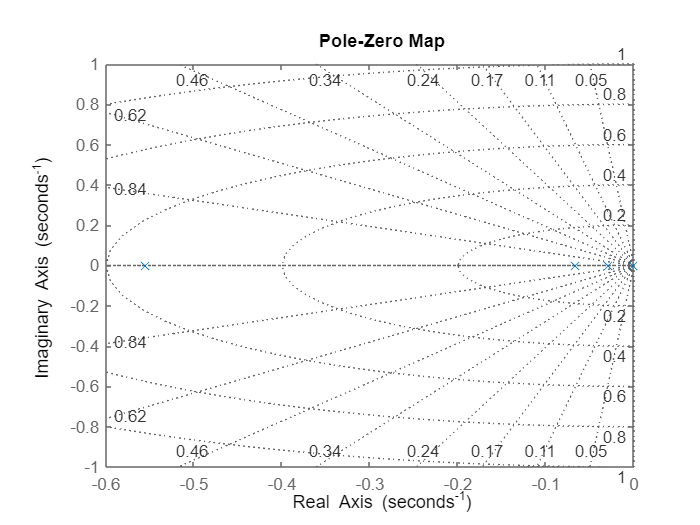

pzmap(syst); grid on

damp(syst)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -2.85e-02     1.00e+00       2.85e-02         3.51e+01    
 -6.67e-02     1.00e+00       6.67e-02         1.50e+01    
 -5.55e-01     1.00e+00       5.55e-01         1.80e+00    


On tous les pôles du système en boucle ouverte sont dans le démi plan complexe gauche, sauf un qui est à l'origine donc en limite de stabilité; ce qui rend le système instable. Tous les pôles sont réel, ce qui informe sur le fait que la réponse de sustème ne sera pas oscillatoire. 

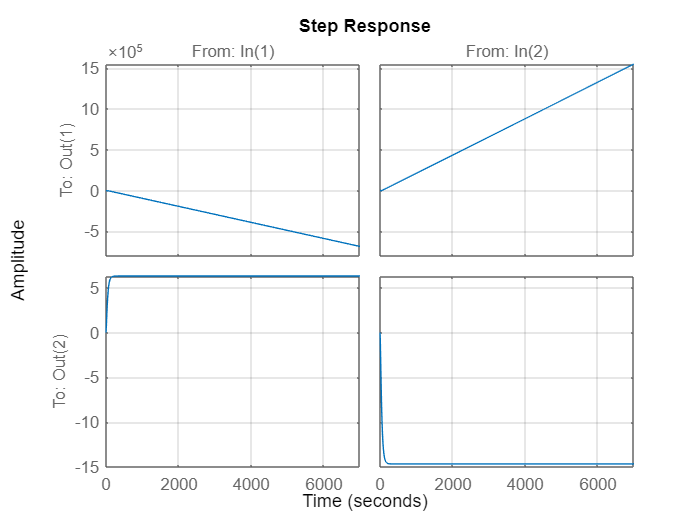

% Step response 
stepplot(syst); grid on ;

on constate que le chacune des entrée affecte les deux sorties du système, ce qui permet de conclure sur l'existence d'un couplage dans le système

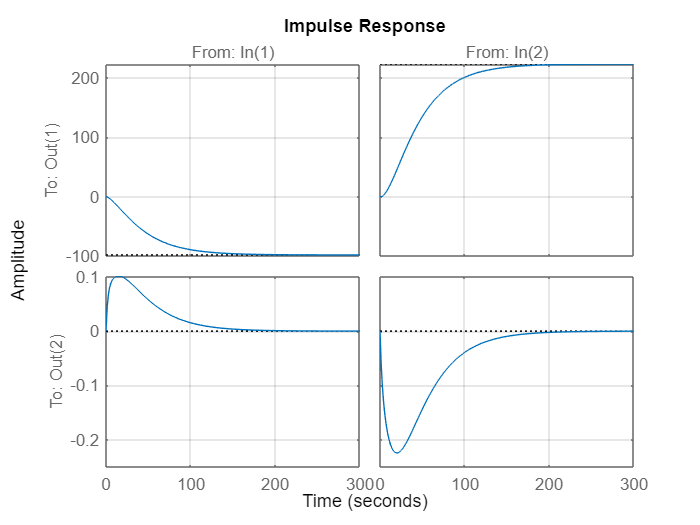

 impulse(syst); grid on;

une augmentation de pr entraine une diminution notable de h et theta et une augmentation de po entraine l'augmentation de h et theta 

## Objective realization

L'idée étant de placer les pôles de sorte à découplé le système, on place les pôles propres $\lambda_1$ et $\lambda_3$ pour avoir un comportement de premier ordre 

de dénominateur $\left(p+\lambda_i \right)$. 

Sachant que le temps de réponse d'un premier ordre est $t_{\textrm{r5}%} =3*\tau \;$ avec $\tau =\frac{1}{\lambda }$ 

Pour garantir la stabilité, on impose que les pôles $\lambda_i \;$soit à partie réelle négative. 

## **Structure propre et commande découplant**

Pour le découplage on souhaite transformer le système avec des état intermediaires qui n'ont pas nécessairement une signification physique, mais qui néanmoins permettrons de pouvoir synthétiser une loi de commande par retour d'état $U=-K\;X+{H\;Y}_c$. On note $V\;$la matrice de transformation telle que $x=V\;x^* \;\;$

le système découplé s'écrit alors : $\left\lbrace \begin{array}{ll}
\dot{\;\;\;x^* \;} =V^{-1} \left(A-\mathrm{BK}\right)V\;x^* +V^{-1} B\;H\;Y_c \; & \\
y=C\;V\;x^*  & 
\end{array}\right.$  $y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
h\\
\theta 
\end{array}\right\rbrack$

Sachant que l'on veut avoir la consigne $y_{\mathrm{c1}} \;$qui n'agit que sur les état intermediaires $x_3^* \;\;\mathrm{et}\;\;x_4^*$ et $y_{\mathrm{c2}} \;$qui n'agit que sur les état intermediaires $x_1^* \;\;\mathrm{et}\;\;x_2^*$ 


$$\left\lbrack \begin{array}{c}
{\dot{x_1 } }^* \\
{\dot{x_2 } }^* \\
{\dot{x_3 } }^* \\
{\dot{x_4 } }^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\lambda_1  & 0 & 0 & 0\\
0 & \lambda_2  & 0 & 0\\
0 & 0 & \lambda_3  & 0\\
0 & 0 & 0 & \lambda_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1^* \\
x_2^* \\
x_3^* \\
x_4^* 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & *_1 \\
0 & *_2 \\
*_3  & 0\\
*_4  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_{\mathrm{c1}} \\
y_{\mathrm{c2}} 
\end{array}\right\rbrack$$


On souhaite avoir  $\begin{array}{l}
y_1 \longrightarrow \left\lbrack x_3^* \;\;\;\;\;\;\;\;\;x_4^* \;\;\right\rbrack \;\\
y_2 \longrightarrow \left\lbrack x_1^* \;\;\;\;\;\;\;\;\;x_2^* \;\;\right\rbrack 
\end{array}$, $\begin{array}{l}
\mathrm{avec}\;\;y=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack V\left\lbrack \begin{array}{c}
x_1^* \\
x_2^* \\
x_3^* \\
x_4^* 
\end{array}\right\rbrack \;\mathrm{donc}\;\mathrm{aura}\;y=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
* & * & * & *\\
* & * & * & *\\
0 & 0 & * & *\\
* & * & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1^* \\
x_2^* \\
x_3^* \\
x_4^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & v_{33}  & v_{34} \\
v_{41}  & v_{42}  & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1^* \\
x_2^* \\
x_3^* \\
x_4^* 
\end{array}\right\rbrack \;\\
y_1 =v_{33} x_3^* +v_{34} x_4^* \\
y_2 =v_{41} x_1^* +v_{42} x_2^* 
\end{array}$

lamda1=-3/100;
lamda2=lamda1*100;
lamda3=-3/80;
lamda4=lamda3*100;

Nlamda2=-inv(lamda2*eye(4,4)-A)*B;
Nlamda1=-inv(lamda1*eye(4,4)-A)*B;
Nlamda3=-inv(lamda3*eye(4,4)-A)*B;
Nlamda4=-inv(lamda4*eye(4,4)-A)*B;


v1_tilde = [0;
            1];
v2_tilde = [0;
            1];
v3_tilde = [1;
            0];
v4_tilde = [1;
            0];

Nlamda3_tilde = Nlamda3(3:4,:);
Nlamda1_tilde = Nlamda1(3:4,:);
Nlamda2_tilde = Nlamda2(3:4,:);
Nlamda4_tilde = Nlamda4(3:4,:);

z1 = inv(Nlamda1_tilde'*Nlamda1_tilde)*transpose(Nlamda1_tilde)*v1_tilde;
z2 = inv(Nlamda2_tilde'*Nlamda2_tilde)*transpose(Nlamda2_tilde)*v2_tilde;
z3 = inv(Nlamda3_tilde'*Nlamda3_tilde)*transpose(Nlamda3_tilde)*v3_tilde;
z4 = inv(Nlamda4_tilde'*Nlamda4_tilde)*transpose(Nlamda4_tilde)*v4_tilde;

v1 = Nlamda1*z1;
v2 = Nlamda2*z2;
v3 = Nlamda3*z3;
v4 = Nlamda4*z4;

V = [v1 v2 v3 v4]

V =    15.4343   15.4330   -0.0375   -3.7500
   -0.0300   -3.0000    0.0000         0
   -0.0000    0.0000    1.0000    1.0000
    1.0001    1.0000   -0.0000         0



Z = [z1 z2 z3 z4];

K = Z*inv(V)

K =    -5.5609   59.2569   -0.2228   93.9932
   -4.4899   -0.0688   -0.1737   71.7690


On s'interesse maintenant au calcul de la matrice de **précommande** H

On a $U=V^{-1} \;\;\Rightarrow \;U\;B\;H=\left\lbrack \begin{array}{cc}
0 & *_1 \\
0 & *_2 \\
*_3  & 0\\
*_4  & 0
\end{array}\right\rbrack \Rightarrow H={\left({\;\left(U\ldotp B\right)}^{\prime } \ldotp \left(U\ldotp B\right)\right)}^{-1} \ldotp {\left(U\ldotp B\right)}^{\prime } \ldotp \left\lbrack \begin{array}{cc}
0 & *_1 \\
0 & *_2 \\
*_3  & 0\\
*_4  & 0
\end{array}\right\rbrack \;$

On a le système découplé qui s'écrit comme suit : 


$$\left\lbrack \begin{array}{c}
{\dot{x_1 } }^* \\
{\dot{x_2 } }^* \\
{\dot{x_3 } }^* \\
{\dot{x_4 } }^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\lambda_1  & 0 & 0 & 0\\
0 & \lambda_2  & 0 & 0\\
0 & 0 & \lambda_3  & 0\\
0 & 0 & 0 & \lambda_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1^* \\
x_2^* \\
x_3^* \\
x_4^* 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & *_1 \\
0 & *_2 \\
*_3  & 0\\
*_4  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_{\mathrm{c1}} \\
y_{\mathrm{c2}} 
\end{array}\right\rbrack \longrightarrow \left\lbrace \begin{array}{l}
{\dot{x_1 } }^* =\lambda_1 x_1^* +*_1 y_{\mathrm{c2}} \;\\
{\dot{x_2 } }^* =\lambda_2 x_2^* +*_2 y_{\mathrm{c2}} \\
{\dot{x_3 } }^* =\lambda_3 x_3^* +*_3 y_{\mathrm{c1}} \\
{\dot{x_4 } }^* =\lambda_4 x_4^* +*_4 y_{\mathrm{c1}} 
\end{array}\right.$$
  


$$H=\left\lbrack \begin{array}{cc}
h_1  & h_2 \\
h_3  & h_4 
\end{array}\right\rbrack$$


Avec 

UB=inv(V)*B;
UB_inv = inv(UB'*UB);
UB_inter = UB_inv*UB';
star1 = (1/5.48)*1/(3*V(4,1));
star2 = 0*1/V(4,2);
star3 = (1/13.19)*1/V(3,3);
star4 = 0*1/V(3,4);
h1 = UB_inter(1,3)*star3 + UB_inter(1,4)*star4; h2 = UB_inter(1,1)*star1 + UB_inter(1,2)*star2;
h3 = UB_inter(2,3)*star3 + UB_inter(2,4)*star4; h4 = UB_inter(2,1)*star1 + UB_inter(2,2)*star2;
H=[h1 h2;h3 h4]

H =    -0.2230    1.4725
   -0.1739   -0.4780


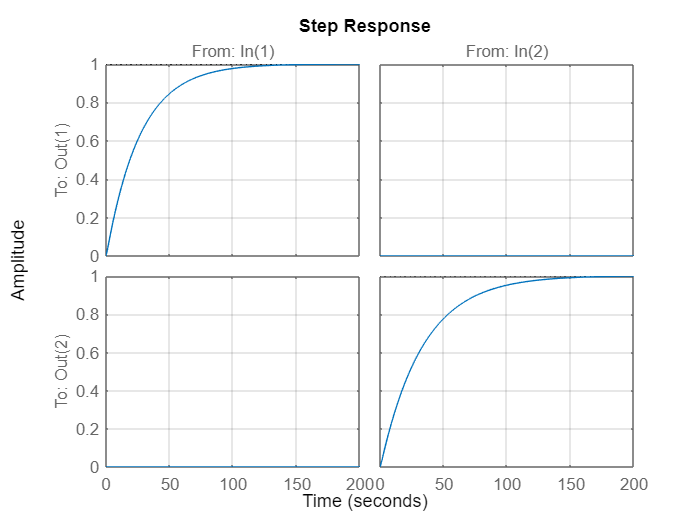

Abf=(A-B*K);
Bbf= B*H;
sys=ss(Abf,Bbf,C,0);
stepplot(sys); grid on;

A travers une démarche empirique nous avons pu déterminer les bonnes valeurs pour les étoiles afin calculer la matrice de précommande qui nous à donné un découplage presque parfait

## Decouplage en mode statique

Afin d'avoir un découplage parfait, on se ramène en régime statique avec $\dot{x} =0$ et on exprime la consigne de la forme$Y_c =C\;x$

On montre que la matrice de précommande peut se déduire de la relation $H=\Omega_{22} +K\;\Omega_{12}$

Avec $\Omega =\left\lbrack \begin{array}{cc}
\Omega_{11}  & \Omega_{12} \\
\Omega_{21}  & \Omega_{22} 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
A & B\\
C & 0
\end{array}\right\rbrack }^{-1}$

Omega_inv = [A        B;
             C   zeros(2,2)];
Omega = inv(Omega_inv);
H = Omega(5:6,5:6) + K*Omega(1:4,5:6)

H =    -0.2228    1.4673
   -0.1737   -0.4763


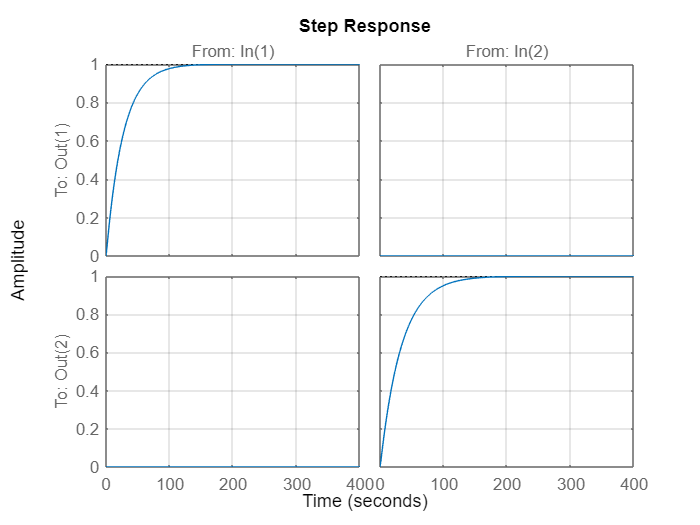

syst_static_decoupled = ss(Abf,B*H,C,0);
stepplot(syst_static_decoupled); grid on;

## Intensive mode placement

## Etude de sensibilité